# **Cylinder**

**Overview**

The `Cylinder` chart creates three-dimensional stacked cylinders, similar to a stacked bar graph. The chart data comprises a nonnegative numeric 2-D matrix (`Data`). The number of stacks is equal to the number of rows of `Data`, and each stack is positioned on the $x$-axis of the chart. The number of cylinders within each stack is equal to the number of columns of `Data`. The heights of the cylinders within each stack correspond to the values contained in each row of `Data`.

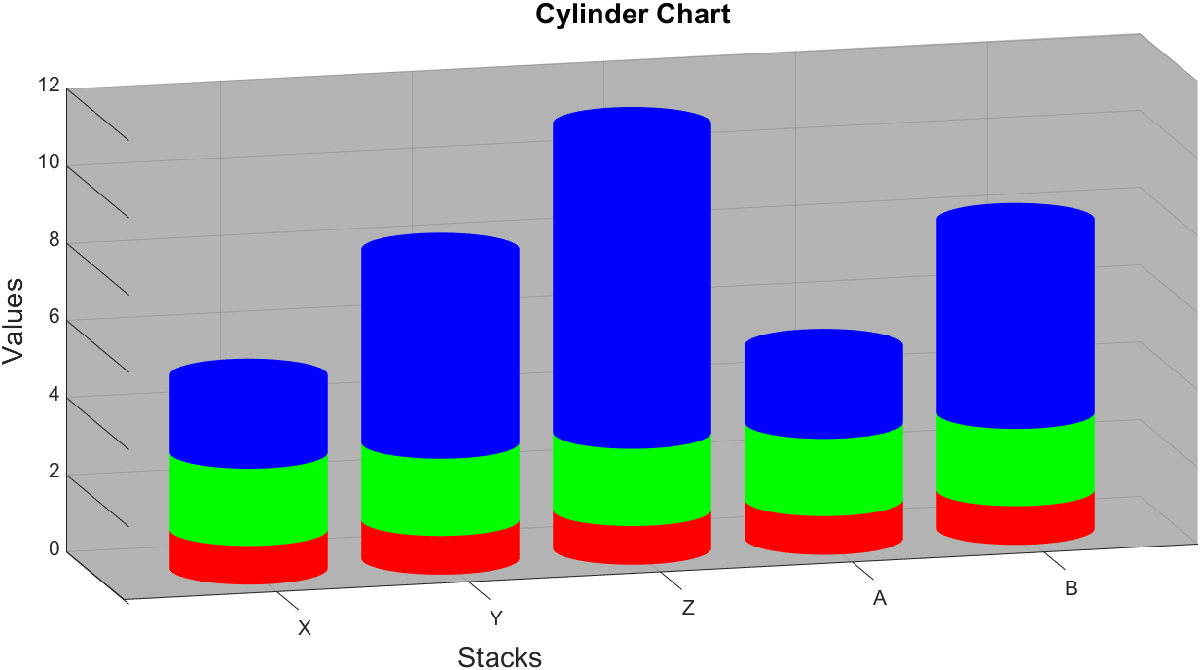

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Cylinder.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Cylinder.m"))) the source code for the `Cylinder` chart.

Documentation for:

- [cylinder](matlab: doc( "cylinder" )): create $x$, $y$ and $z$-coordinates for a cylinder

## Create sample chart data.

The data in each row corresponds to a single stack, and the data in each column corresponds to the heights of the individual cylinders within the stack.

Y = [2, 2, 3;
    2, 5, 6;
    2, 8, 9;
    2, 11, 12];

## Create a figure for the chart.

f = exampleFigure( "Name", "Cylinder Example", ...
    "Color", "w" );

## Create the chart, specifying the parent and input data.

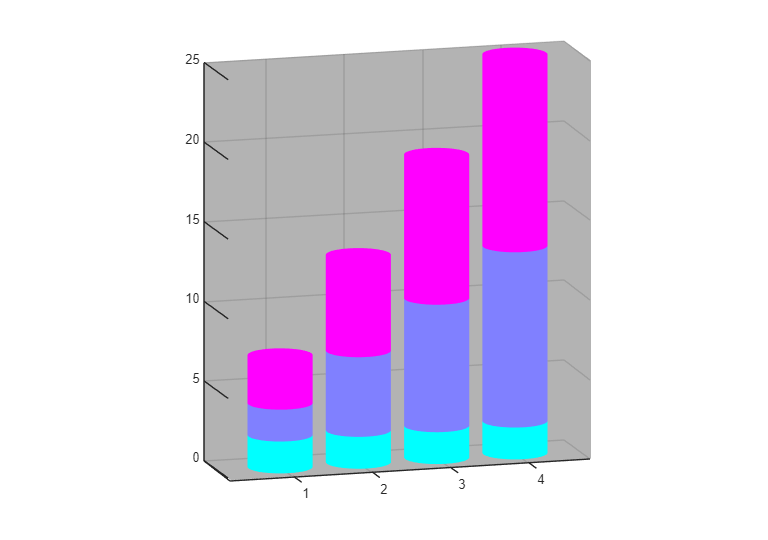

C = chart.Cylinder( "Parent", f, ...    
    "Data", Y );

## Annotate the chart.

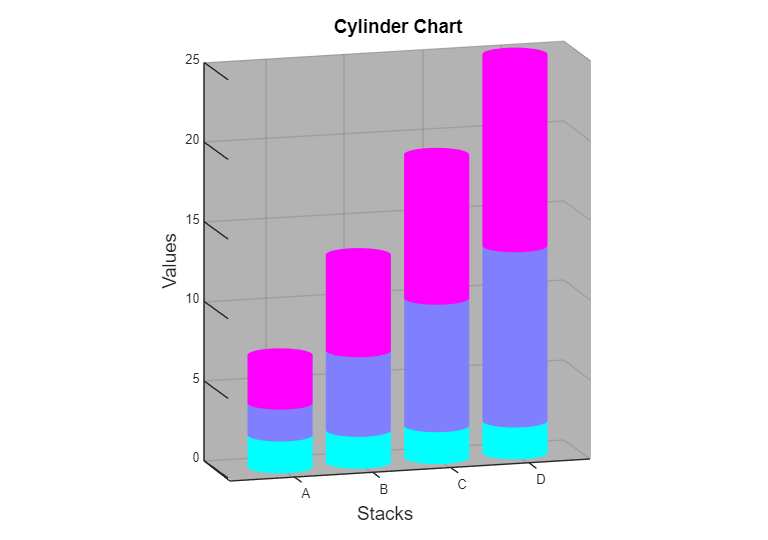

xlabel( C, "Stacks", "FontSize", 14 )
zlabel( C, "Values", "FontSize", 14 )
title( C, "Cylinder Chart", "FontSize", 14 )
xticklabels( C, ["A", "B", "C", "D"] )

## Change the cylinder face colors.

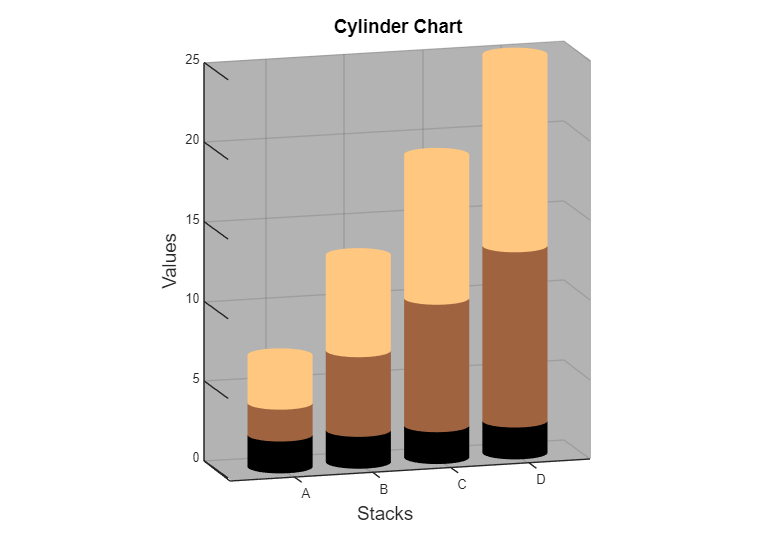

C.FaceColors = copper( 3 );

## Truncate the current chart data by removing a stack.

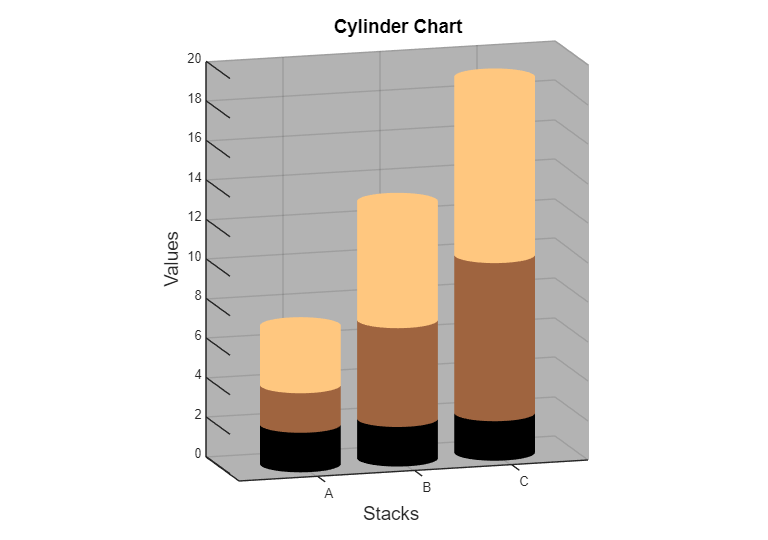

C.Data = C.Data(1:3, :);

## Extend the current chart data by creating multiple stacks.

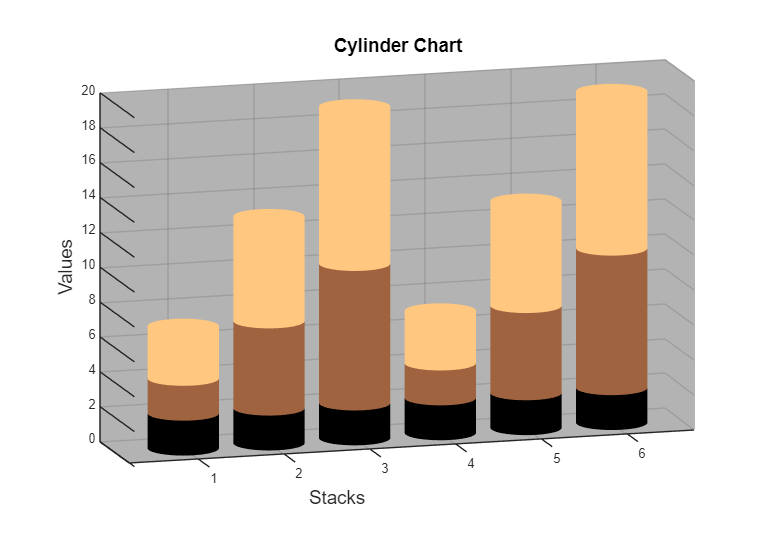

C.Data = [C.Data; C.Data];

## Change the data by increasing the number of layers.

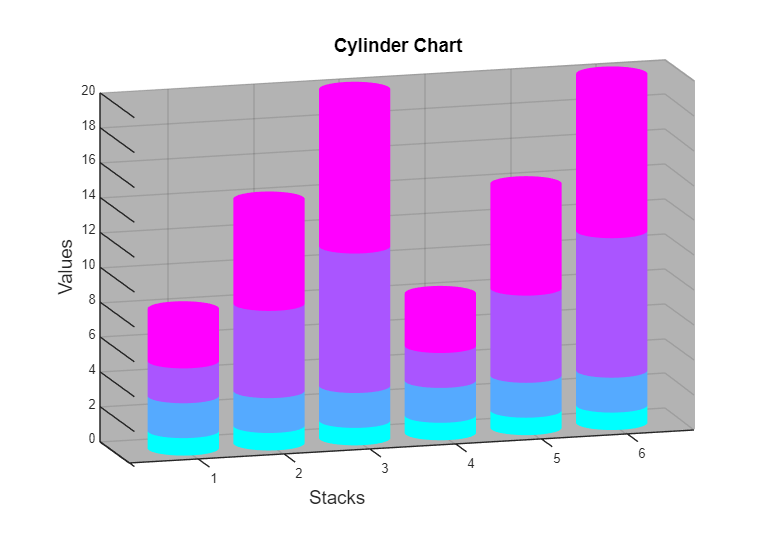

C.Data = [ones(size(C.Data, 1), 1), C.Data];

## Modify the axis tick labels and truncate the chart data.

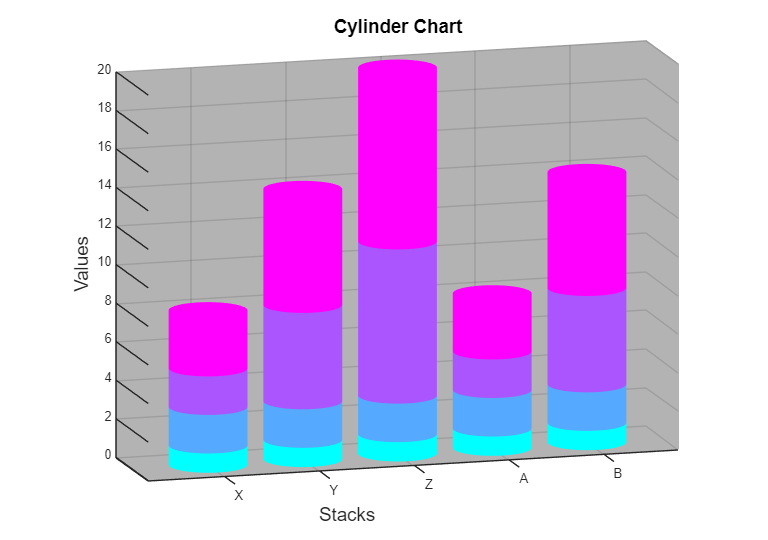

xticklabels( C, ["X", "Y", "Z", "A", "B", "C"] )
C.Data = C.Data(1:end-1, :);

## Remove the top layer of chart data.

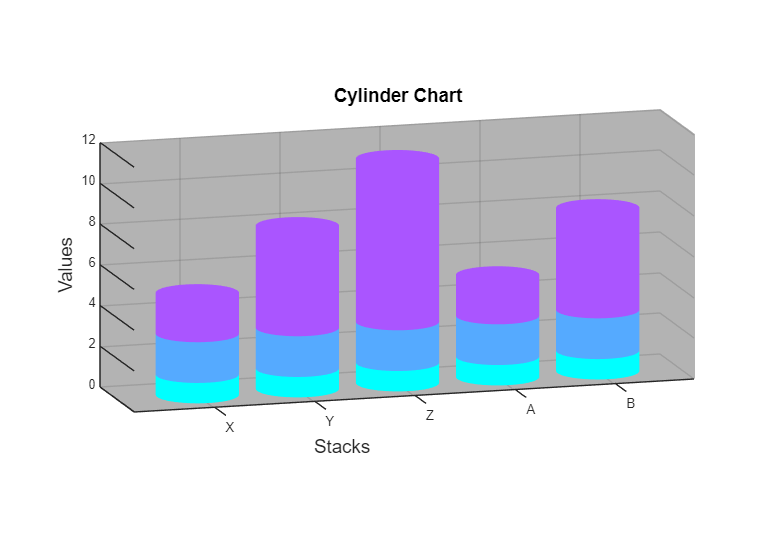

C.Data = C.Data(:, 1:end-1);

## Change the chart view and face colors.

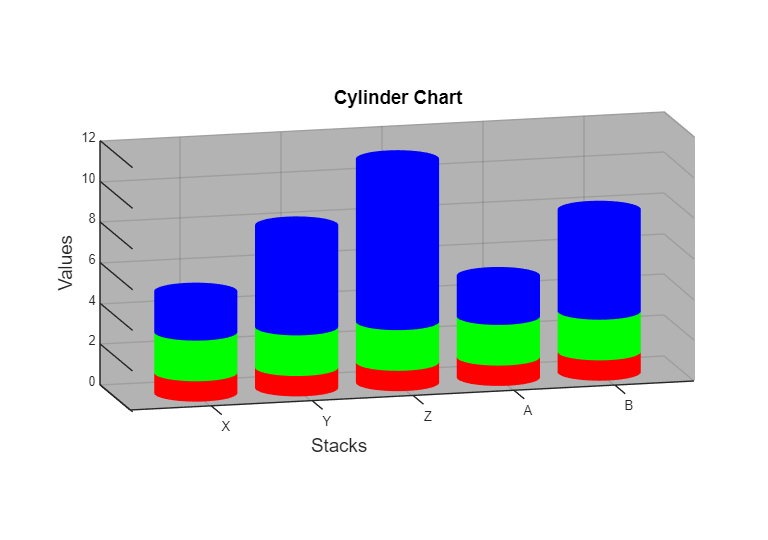

set( C, "View", [-14, 12], "FaceColors", hsv( 3 ) )

*Copyright 2018-2022 The MathWorks, Inc.*